## First version of the SDE solver with the suggested parameters

These parameters are left constant thoughout the whole assignment.

S0 = 14;
K = 15;
r = 0.1;
sigma = 0.25;
T = 0.5;

Calculate the estimated price of a call option, using the Euler method

N_samples = 100000;
gamma = 0.8;
n_timeponts = 100;
V_vec = STD_solverv1(N_samples, n_timeponts, T, S0, sigma, gamma, K, r);
V_est = exp(-r * T) * mean(V_vec);

disp("Estimated price of call option")

Estimated price of call option


disp("V = " + num2str(V_est))

V = 0.45294


## Error analysis of first version

The sample error as a function of number of samples.


gamma = 1;
V_analytical = bsexact(sigma, r, K, T, S0) % Theoretical value for the given parameters.

V_analytical = 0.8670

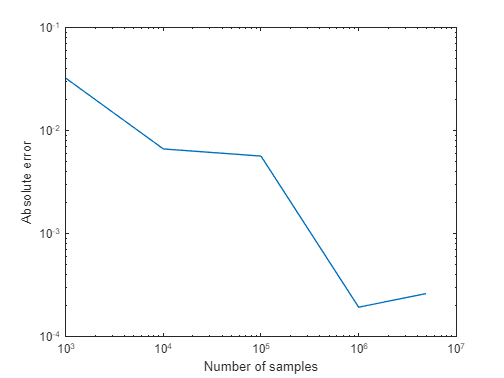


N_samples_vec = [1000, 10000, 100000, 1000000, 5000000];
V_est_vec1 = zeros(1,length(N_samples_vec));

n_timeponts = 256;

for k = 1:length(N_samples_vec)

    N_samples = N_samples_vec(k);
    V_vec1 = STD_solverv1(N_samples, n_timeponts,T, S0, sigma, gamma, K, r);
    V_est_vec1(k) = exp(-r * T) * mean(V_vec1);
end

err_sample1 = abs(V_analytical -  V_est_vec1);
figure()
loglog(N_samples_vec, err_sample1)
xlabel("Number of samples")
ylabel("Absolute error")

To obtain the sample error as a function of the number of sample paths we estimate the option price using different amount of sample paths. Then we can calculate the error using the theoretical value obtained by the Black Scholes equation. The sample error should be going down with an increase in the number of samples, which our results confirm. Since we keep the timestep low, we can assume the discretisation error to be negligable. 

p = polyfit(log(N_samples_vec), log(err_sample1),1);
disp("Estimated rate of convergence: " + num2str(-p(1)))

Estimated rate of convergence: 0.61345


The discretization error

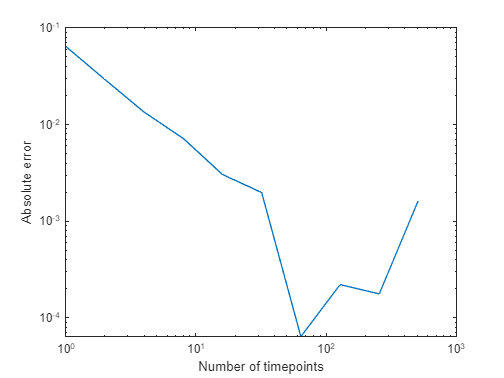

N_samples = 5000000;
n_points_vec = 2 .^ [0, 1, 2, 3, 4, 5, 6, 7, 8,9];
V_est_vec1 = zeros(1,length(n_points_vec));

for k = 1:length(n_points_vec)

    n_timeponts = n_points_vec(k);
    V_vec1 = STD_solverv1(N_samples, n_timeponts, T, S0, sigma, gamma, K, r);
    V_est_vec1(k) = exp(-r * T) * mean(V_vec1);
end
    
err_time1 = abs(V_analytical -  V_est_vec1);

figure()
loglog(n_points_vec, err_time1)
xlabel("Number of timepoints")
ylabel("Absolute error")

Similarly we can calculate the discretization error as a function of the time step. We calculate different estimates of the option price and compare with the result from the Black Scholes equation, and calculate the error. The discretization error should be going down when the number of time points increases, which our results confirms. When calculating the discretization error we keep the number of samples high so we can neglect the sample error.

p = polyfit(log(n_points_vec), log(err_time1),1);
disp("Estimated rate of convergence: " + num2str(-p(1)))

Estimated rate of convergence: 0.90817


## SDE solver with anthetic variates

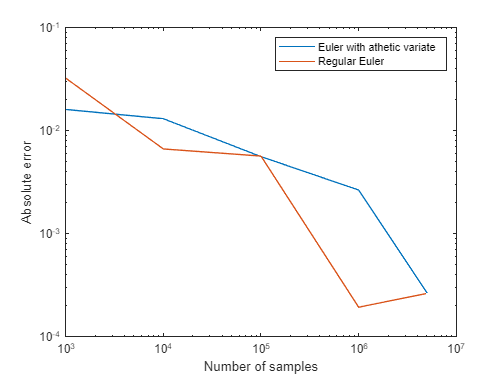

V_est_vec2 = zeros(1,length(N_samples_vec));
n_timeponts = 256;

for k = 1:length(N_samples_vec)
    N_samples = N_samples_vec(k)/2; % We divide by 2 since the anthetic variate methods simulate two sample paths
                                    % for every iteration
    V_vec2 = STD_solverv1_anth(N_samples, n_timeponts,T, S0, sigma, gamma, K, r);
    V_est_vec2(k) = exp(-r * T) * mean(V_vec2);
end

err_sample1_anth = abs(V_analytical -  V_est_vec2);
figure()
loglog(N_samples_vec, err_sample1_anth)
hold on;
loglog(N_samples_vec, err_sample1)
hold off;
xlabel("Number of samples")
ylabel("Absolute error")
legend("Euler with athetic variate","Regular Euler")

Antithetic variates did not seem to give a significant improvement in this case. 


p = polyfit(log(N_samples_vec), log(err_sample1_anth),1);
disp("Estimated rate of convergence: " + num2str(-p(1)))

Estimated rate of convergence: 0.44039


## SDE solver with anthetic variates and Runge-Kutta scheme


V_vec = STD_solverv2(N_samples, n_timeponts, T, S0, sigma, gamma, K, r);


V_est = exp(-r * T) * mean(V_vec);
%V_std = std(V_vec);

disp("Estimated price of call option")

Estimated price of call option


disp("V = " + num2str(V_est))

V = 0.86629


## Gamma versus the price

In this section we examine the relationship between gamma and the value of the option.

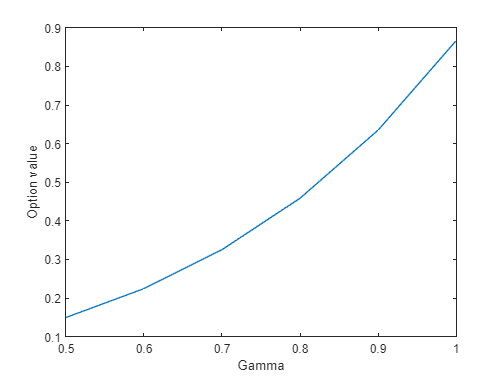

gammavec = 0.5:0.1:1;
V_est_vec = zeros(1, length(gammavec));
N_samples = 1E6;
n_timeponts = 256;
ind = 1;
for gamma = gammavec
    
    V_vec = STD_solverv2(N_samples, n_timeponts, T, S0, sigma, gamma, K, r);
    V_est_vec(ind) = exp(- r * T) * mean(V_vec);
    ind = ind + 1;
end

figure()
plot(gammavec, V_est_vec)
xlabel("Gamma")
ylabel("Option value")

As we can see from our results, the price of a CEV (Constant elasticity of variance model) modeled option increases when gamma increases. An increase in gamma leads to an increased variance which leads to an increase in the price for an option like this.

## The discretization error analysis of the second version, Euler versus Runge-Kutta

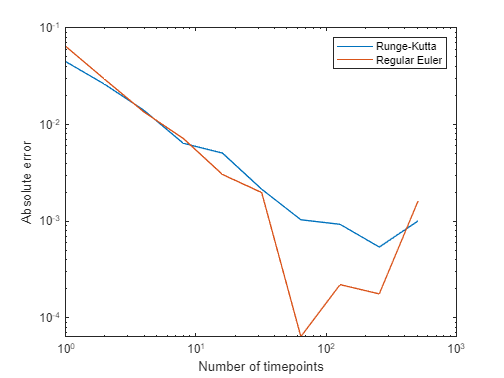

N_samples = 5000000 / 2;
V_est_vec = zeros(1,length(n_points_vec));

for k = 1:length(n_points_vec)

    n_timeponts = n_points_vec(k);
    V_vec = STD_solverv2(N_samples, n_timeponts, T, S0, sigma, gamma, K, r);
    V_est_vec(k) = exp(-r * T) * mean(V_vec);
end
    
err_time3 = abs(V_analytical -  V_est_vec);

figure()
loglog(n_points_vec, err_time3)

hold on;
loglog(n_points_vec, err_time1)
hold off;
xlabel("Number of timepoints")
ylabel("Absolute error")
legend("Runge-Kutta","Regular Euler")

p = polyfit(log(n_points_vec), log(err_time3),1);
disp("Estimated rate of convergence: " + num2str(-p(1)))

Estimated rate of convergence: 0.7094


As we can see, the convergence rate for the Euler method and the Runge-Kutta method is very similar. For the diffusion term Euler has a convergence order of the square root of the time step, and Runge Kutta has a convergence order of the time step. Both methods convergence order for the drift term is the time step. Depending on how big a impact the diffusion term has, the more different the convergence rate is when comparing the methods. Therefor it seems that in this case the diffusion term don't have a big impact, which leads to the convergence order of both methods being very similar. 